% Laboratorio 4

%%
clc
clear
close all
ws = [-100 100 -100 100 -10 70]/3;

plot_options0 = {'workspace',ws,'scale',.5,'view',[-25 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L0=4;
L1=10.5;
L2=10.5;
L3=6.5;

L(1) = Link('revolute','d',L0,'a',0,'alpha',-pi/2,'offset',0,'standard');
L(2) = Link('revolute','d',0,'a',-L1,'alpha',0,'offset',pi/2,'standard');
L(3) = Link('revolute','d',0,'a',-L2,'alpha',0,'offset',pi/2,'standard');
L(4) = Link('revolute','d',0,'a',0,'alpha',-pi/2,'offset',pi/2,'standard');
L(5) = Link('revolute','d',L3,'a',0,'alpha',0,'offset',0,'standard');

Robot0 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options0)

 
Robot0 = 
 
Robot RRRR:: 5 axis, RRRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|    -1.5708|          0|
|  2|         q2|          0|      -10.5|          0|     1.5708|
|  3|         q3|          0|      -10.5|          0|     1.5708|
|  4|         q4|          0|          0|    -1.5708|     1.5708|
|  5|         q5|        6.5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


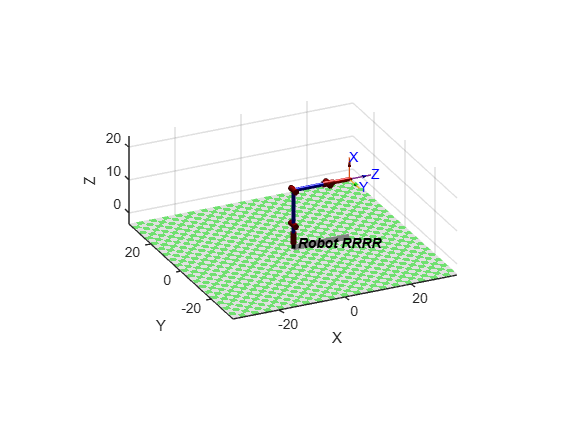

Robot0.plot(deg2rad([0 0 0 0 0]))


plot_options1 = {'workspace',ws,'scale',5,'view',[-25 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot1 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options1)

 
Robot1 = 
 
Robot RRRR:: 5 axis, RRRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|    -1.5708|          0|
|  2|         q2|          0|      -10.5|          0|     1.5708|
|  3|         q3|          0|      -10.5|          0|     1.5708|
|  4|         q4|          0|          0|    -1.5708|     1.5708|
|  5|         q5|        6.5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


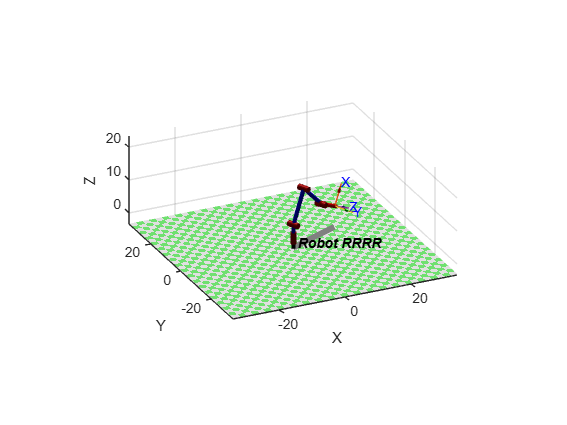

Robot1.plot(deg2rad([ 25, 25, 20,-20, 0]))



plot_options2 = {'workspace',ws,'scale',5,'view',[-25 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot2 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options2)

 
Robot2 = 
 
Robot RRRR:: 5 axis, RRRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|    -1.5708|          0|
|  2|         q2|          0|      -10.5|          0|     1.5708|
|  3|         q3|          0|      -10.5|          0|     1.5708|
|  4|         q4|          0|          0|    -1.5708|     1.5708|
|  5|         q5|        6.5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


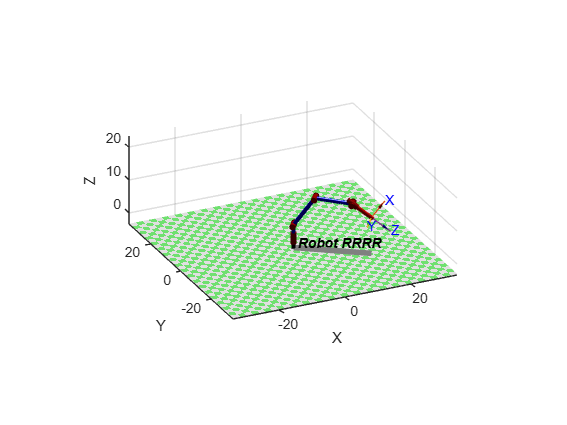

Robot2.plot(deg2rad([-35,35,-30, 30, 0]))


plot_options3 = {'workspace',ws,'scale',5,'view',[-25 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot3 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options3)

 
Robot3 = 
 
Robot RRRR:: 5 axis, RRRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|    -1.5708|          0|
|  2|         q2|          0|      -10.5|          0|     1.5708|
|  3|         q3|          0|      -10.5|          0|     1.5708|
|  4|         q4|          0|          0|    -1.5708|     1.5708|
|  5|         q5|        6.5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


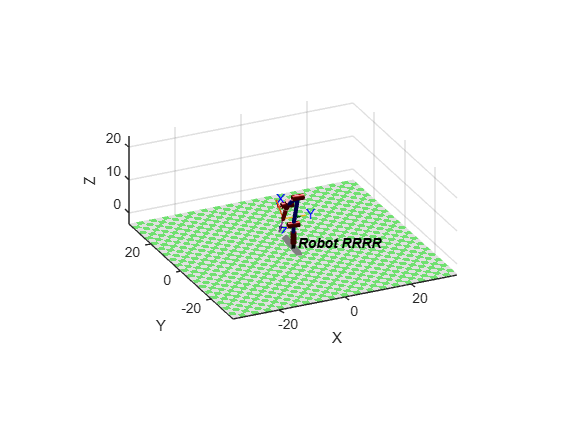

Robot3.plot(deg2rad([85,-20, 55, 25, 0]))


plot_options4 = {'workspace',ws,'scale',.5,'view',[-25 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot4 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options4)

 
Robot4 = 
 
Robot RRRR:: 5 axis, RRRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|    -1.5708|          0|
|  2|         q2|          0|      -10.5|          0|     1.5708|
|  3|         q3|          0|      -10.5|          0|     1.5708|
|  4|         q4|          0|          0|    -1.5708|     1.5708|
|  5|         q5|        6.5|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


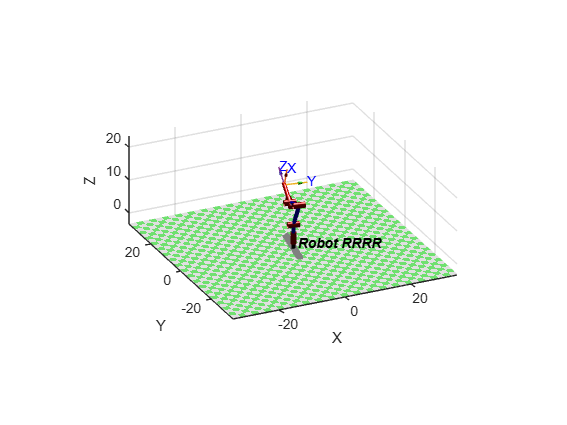

Robot4.plot(deg2rad([80,-35, 55,-45, 0])) 

q1 = 0; % en radianes
q2 = 0; % en radianes
q3 = 0; % en radianes
q4 = 0; % en radianes
q5 = 0; % en radianes
chain = "Rz(q1) Tz(L0) Rx(-pi/2) Rz(q2+pi/2) Tx(-L1) Rz(q3+pi/2) Tx(-L2) Rz(q4+pi/2) Rx(-pi/2) Rz(q5) Tz(L3)"

chain = "Rz(q1) Tz(L0) Rx(-pi/2) Rz(q2+pi/2) Tx(-L1) Rz(q3+pi/2) Tx(-L2) Rz(q4+pi/2) Rx(-pi/2) Rz(q5) Tz(L3)"

%MTH =   'Rz(q1) Tz(4) Rx(-90) Rz(q2+pi/2) Tx(-10.5) Rz(q3+pi/2) Tx(-10.5) Rz(q4+pi/2) Rx(-90) Rz(q5) Tz(6.5)'
%MTH = trchain(Robot0)

MTH = trotz(q1)*transl(0,0,L0)*trotx(-pi/2)*trotz(q2+pi/2)*transl(-L1,0,0)*trotz(q3+pi/2)*transl(-L2,0,0)*trotz(q4+pi/2)*trotx(-pi/2)*trotz(q5)*transl(0,0,L3)

MTH =          0         0    1.0000   17.0000
         0   -1.0000         0         0
    1.0000         0         0   14.5000
         0         0         0    1.0000


MTH = $\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 17\\
0 & -1 & 0 & 0\\
1 & 0 & 0 & 14\ldotp 5\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$